# Teaching Quantum Mechanics with MATLAB

R. Garcia, A. Zozulya, and J. Stickney

*Department of Physics, Worcester Polytechnic Institute, Worcester, MA 01609*

February 1, 2008

Adapted by Paul Kassebaum

October 11, 2016

## Abstract

Among the ideas to be conveyed to students in an introductory quantum course, we have the pivotal idea championed by Dirac that functions correspond to column vectors (kets) and that diﬀerential operators correspond to matrices (ket-bras) acting on those vectors. The MATLAB (matrix-laboratory) programming environment is especially useful in conveying these concepts to students because it is geared towards the type of matrix manipulations useful in solving introductory quantum physics problems. In this article, we share MATLAB codes which have been developed at WPI, focusing on 1D problems, to be used in conjunction with Griﬃths’ introductory text.

## Introduction

Two key concepts underpinning quantum physics are the Schrodinger equation and the Born probability equation. In 1930 Dirac introduced bra-ket notation for state vectors and operators.[1] This notation emphasized and clariﬁed the role of inner products and linear function spaces in these two equations and is fundamental to our modern understanding of quantum mechanics. The Schrodinger equation tells us how the state $\Psi$ of a particle evolves in time. In bra-ket notation, it reads


$$(1) \quad i\hbar \frac{d}{dt} |\Psi\rangle = H |\Psi\rangle .$$


where $H$ is the Hamiltonian operator and $|\Psi\rangle$ is a ket or column vector representing the quantum state of the particle. When a measurement of a physical quantity $A$ is made on a particle initially in the state $\Psi$, the Born equation provides a way to calculate the probability $P(A_o)$ that a particular result $A_o$ is obtained from the measurement. In bra-ket notation, it reads[2] 


$$(2) \quad P(A_o) \sim |\langle A_o | \Psi \rangle |^2,$$


where if $|A_o\rangle$ is the state vector corresponding to the particular result $A_o$ having been measured, $\langle A_o | = | A_o \rangle ^\dagger$ is the corresponding bra or row vector and $\langle A_o | \Psi \rangle$ is thus the inner product between $|A_o \rangle$ and $|\Psi\rangle$. In the Dirac formalism, the correspondence between the wavefunction $\Psi(\overrightarrow{x})$ and the ket $|\Psi\rangle$ is set by the relation $\Psi(\overrightarrow{x}) = \langle \overrightarrow{x} | \Psi \rangle$, where $|\overrightarrow{x}\rangle$ is the state vector corresponding to the particle being located at $\overrightarrow{x}$. Thus we regard $\Psi(\overrightarrow{x})$ as a component of a state vector $|\Psi\rangle$, just as we usually[3] regard $a_i = \hat{i} \cdot \overrightarrow{a}$ as a component of $\overrightarrow{a}$ along the direction $\hat{i}$. Similarly, we think of the Hamiltonian operator as a matrix


$$(3) \quad H = \int d^3\overrightarrow{x} \, |\overrightarrow{x}\rangle \left\{ \frac{1}{2m} \left( \frac{\hbar}{i} \frac{\partial}{\partial\overrightarrow{x}} \right)^2 \Psi(\overrightarrow{x}, t) + U(\overrightarrow{x}) \right\} \langle \overrightarrow{x} |$$


acting on the space of kets.

While an expert will necessarily regard Eqs.(1-3) as a great simpliﬁcation when thinking of the content of quantum physics, the novice often understandably reels under the weight of the immense abstraction. We learn much about student thinking from from the answers given by our best students. For example, we ﬁnd a common error when studying 1D quantum mechanics is a student treating $\Psi(x)$ and $|\Psi\rangle$ interchangeably, ignoring the fact that the ﬁrst is a scalar but the ket corresponds to a column vector. For example, they may write incorrectly


$$(4) \quad \langle p | \Psi \rangle |x \rangle = |\Psi \rangle \langle p | x \rangle \quad \text{(incorrect!)}$$


or some similar abberation. To avoid these types of misconceptions, a number of educators and textbook authors have stressed incorporating a numerical calculation aspect to quantum courses.[4,5,6,7,8,9] The motive is simple. Anyone who has done numerical calculations can’t help but regard a ket $|\Psi \rangle$ as a column vector, a bra $\langle \Psi |$ as a row vector and an operator $H$ as a matrix because that is how they concretely represented in the computer. Introducing a computational aspect to the course provides one further beneﬁt: it gives the beginning quantum student the sense that he or she is being empowered to solve real problems that may not have simple, analytic solutions.

With these motivations in mind, we have developed MATLAB codes[10] for solving typical 1D problems found in the ﬁrst part of a junior level quantum course based on Griﬃth’s book.[11] We chose MATLAB for our programming environment because the MATLAB syntax is especially simple for the typical matrix operations used in 1D quantum mechanics problems and because of the ease of plotting functions. While some MATLAB numerical recipes have previously been published by others,[12,13] the exercises we share here are special because they emphasize simplicity and quantum pedagogy, not numerical eﬃciency. Our point has been to provide exercises which show students how to numerically solve 1D problems in such a way that emphasizes the column vector aspect of kets, the row vector aspect of bras and the matrix aspect of operators. Exercises using more eﬃcient MATLAB ODE solvers or ﬁnite-element techniques are omitted because they do not serve this immediate purpose. In part II of this article, we hope to share MATLAB codes which can be used in conjunction with teaching topics pertaining to angular momentum and non-commuting observables.

## 1. Functions as Vectors

To start students thinking of functions as column vector-like objects, it is very useful to introduce them to plotting and integrating functions in the MATLAB environment. Interestingly enough, the plot command in MATLAB takes vectors as its basic input element. As shown in Program 1 below, to plot a function $f(x)$in MATLAB, we ﬁrst generate two vectors: a vector of $x$ values and a vector of $y$ values where $y = f(x)$. The command `plot(x,y,′r′)` then generates a plot window containing the points $(x_i, y_i)$displayed as red points (`′r′`). Having speciﬁed both $x$ and $y$, to evaluate the deﬁnite integral $\int_{-L}^{L} y \, dx$, we need only sum all the $y$ values and multiply by $dx$.

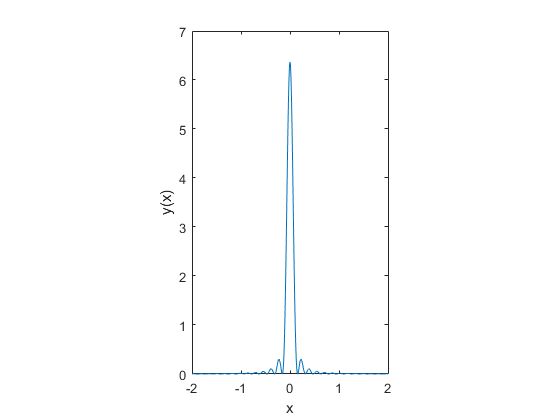

%---------------------------------------------------------------- 
% Program 1: Numerical Integration and Plotting using MATLAB 
%---------------------------------------------------------------- 
N = 1e6;                  % No. of points.
L = 500;                  % Range of x: from -L to L.
x = linspace(-L, L, N).'; % Generate column vector with N 
                          % x values ranging from -L to L.
dx = x(2) - x(1);         % Distance between adjacent points.

% Alternative Trial functions: 
% To select one, delete the comment character '%' at the beginning.

%y = exp(-x.^2/16);                   % Gaussian centered at x=0.
%y = ((2/pi)^0.5) * exp(-2*(x-1).^2); % Normed Gaussian at x=1.
%y = (1-x.^2).^-1;                    % Symmetric fcn, blows up at x=1.
%y = (cos(pi*x)).^2;                  % Cosine fcn.
%y = exp(i*pi*x);                     % Complex exponential.
%y = sin(pi*x/L) .* cos(pi*x/L);      % Product of sinx times cosx.
%y = sin(pi*x/L) .* sin(pi*x/L);      % Product of sin(nx) times sin(mx).
%A = 100; y = sin(x*A) ./ (pi*x);     % Rep. of delta fcn.
A = 20; y = (sin(x*A).^2) ./ (pi*(A*x.^2)); % Another rep. of delta fcn.

% Observe: a function y(x) is numerically represented by a vector!

% Plot a vector/function.
plot(x,y);        % Plots vector y vs x.
axis([-2 2 0 7]); % Optimized for sin(x).^2 ./ (pi * x.^2).
%plot(x,real(y),’r’, x, imag(y), ’b’); % Plots real&imag y vs x.
%axis([-2 2 -8 40]);                   % Optimized for sin(x) ./ (pi * x).
xlabel('x');
ylabel('y(x)');
daspect([1 1 1]);


% Numerical Integration 
I_simp = sum(y)   * dx; % Simple numerical integral of y.
I_trap = trapz(y) * dx; % Integration using trapezoidal rule.

format long;
disp(I_simp);

   0.999968168112938



disp(I_trap);

   0.999968168106993



format short;

## 2. Differential Operators as Matrices

Just as $f(x)$ is represented by a column vector $|f\,\rangle$ in the computer, for numerical purposes a diﬀerential operator $\hat{D}$ acting on $f(x)$ is reresented by a matrix $D$ that acts on $|f\,\rangle$. As illustrated in Program 2, MATLAB provides many useful, intuitive, well-documented commands for generating matrices $D$ that correspond to a given $\hat{D}$.[10] Two examples are the commands `ones` and `diag`. The command `ones(a,b)` generates an $a\times b$ matrix of ones. The command `diag(A,n)` generates a matrix with the elements of the vector $A$ placed along the $n\text{th}$ diagonal and zeros everywhere else. The central diagonal corresponds to $n = 0 $, the diagonal above the center one corresponds to $n = 1$, etc$\ldots$.

An exercise we suggest is for students to verify that the derivative matrix is not Hermitian while the derivative matrix times the imaginary number $i$ is. This can be very valuable for promoting student understanding if done in conjunction with the proof usually given for the diﬀerential operator.

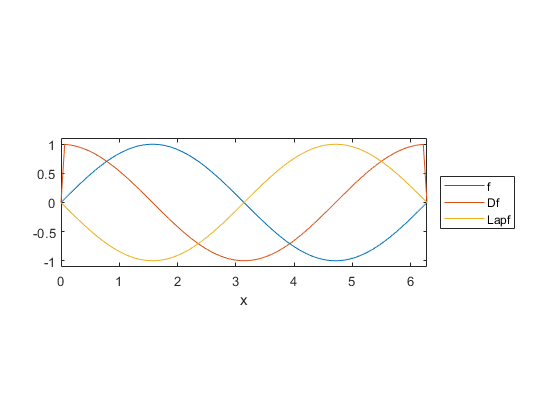

%----------------------------------------------------------------
% Program 2: Calculate first and second derivative numerically
% showing how to write differential operator as a matrix.
%----------------------------------------------------------------
% Parameters for solving problem in the interval 0 < x < L.
L = 2*pi;                % Interval Length.
N = 100;                 % No. of coordinate points.
x = linspace(0, L, N).'; % Coordinate vector.
dx = x(2) - x(1);        % Coordinate step.

% Two-point finite-difference representation of Derivative.
D = (diag(ones((N-1),1),1) - diag(ones((N-1),1),-1)) / (2*dx);
% Next modify D so that it is consistent with f(0) = f(L) = 0.
D(1,   1) = 0; D(  1, 2) = 0; D(2, 1) = 0; % So that f(0) = 0.
D(N, N-1) = 0; D(N-1, N) = 0; D(N, N) = 0; % So that f(L) = 0.

% Three-point finite-difference representation of Laplacian.
Lap = (diag(ones((N-1),1),-1) - 2*diag(ones(N,1),0) ... 
     + diag(ones((N-1),1), 1)) / (dx^2);

% Next modify Lap so that it is consistent with f(0) = f(L) = 0.
Lap(1,   1) = 0; Lap(  1, 2) = 0; Lap(2, 1) = 0; % So that f(0) = 0.
Lap(N, N-1) = 0; Lap(N-1, N) = 0; Lap(N, N) = 0; % So that f(L) = 0.

% To verify that D*f corresponds to taking the derivative of f
% and Lap*f corresponds to taking a second derviative of f,
% define f = sin(x) or choose your own f,
f = sin(x); 
% and try the following: 
Df   =   D * f;
Lapf = Lap * f; 
plot(x,    f, ...
     x,   Df, ...
     x, Lapf); 
legend('f','Df','Lapf','Location','EastOutside');
xlabel('x');
axis([0 2*pi -1.1 1.1]);
daspect([1 1 1]);

% To display the matrix D on screen, simply type D and return ...
disp(D);   % Displays the matrix D in the workspace 

  Columns 1 through 18

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    7.8782         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -7.8782         0    7.8782         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -7.8782         0    7.8782         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -7.8782         0    7.8782         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   -7.8782         0    7.8782 

disp(Lap); % Displays the matrix Lap

  Columns 1 through 18

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0 -496.5245  248.2622         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  248.2622 -496.5245  248.2622         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0  248.2622 -496.5245  248.2622         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0  248.2622 -496.5245  248.2622         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0  248.2622 -496.5245  248.2622 

## 3. Infinite Square Well

When solving Eq. (1), the method of separation of variables entails that as an intermediate step we look for the separable solutions 


$$(5) \quad |\Psi_E (t) \rangle = |\Psi_E(0)\rangle \, \exp(-i E t / \hbar),$$


where $|\Psi_E(0)\rangle$ satisfies the time-independent Schrodinger equation


$$(6) \quad H\, |\Psi_E(0)\rangle = E\,|\Psi_E(0)\rangle.$$


In solving Eq. (6) we are solving for the eigenvalues $E$ and eigenvectors $|\Psi_E(0)\rangle$ of $H$. In MATLAB, the command `[V,E] = eig(H)` does precisely this: it generates two matrices. The ﬁrst matrix $V$ has as its columns the eigenvectors $|\Psi_E(0)\rangle$. The second matrix $E$ is a diagonal matrix with the eigenvalues $E_i$ corresponding to the eigenvectors $|\Psi_{E_i}(0)\rangle$ placed along the central diagonal. We can use the command `E = diag(E)` to convert this matrix into a column vector. In Program 3, we solve for the eigenfunctions and eigenvalues for the inﬁnite square well Hamiltonian. For brevity, we omit the commands setting the parameters $L$, $N$, $x$, and $dx$.

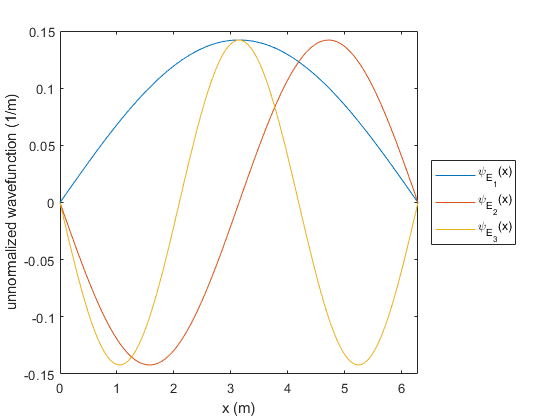

%----------------------------------------------------------------
% Program 3: Matrix representation of differential operators,
% Solving for Eigenvectors & Eigenvalues of Infinite Square Well.
%----------------------------------------------------------------
% For brevity we omit the commands setting the parameters L, N,
% x and dx. We also omit the commands defining the matrix Lap.
% These would be the same as in Program 2 above.

% Total Hamiltonian where hbar=1 and m=1.
hbar = 1; 
m = 1; 
H = -(1/2)*(hbar^2/m)*Lap; 

% Solve for eigenvector matrix V and eigenvalue matrix E of H.
[V, E] = eig(H);

% Plot lowest 3 eigenfunctions.
plot(x,V(:,3), x,V(:,4), x,V(:,5));
legend('\psi_{E_1}(x)','\psi_{E_2}(x)','\psi_{E_3}(x)','Location','EastOutside');
xlabel('x (m)');
ylabel('unnormalized wavefunction (1/m)');
ax = gca; % Get the Current Axes object
ax.XLim = [0 2*pi];

disp(E);       % display eigenvalue matrix.

  Columns 1 through 18

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.1250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.4998         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.1242         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.9973         0 

disp(diag(E)); % display a vector containing the eigenvalues.

         0
         0
    0.1250
    0.4998
    1.1242
    1.9973
    3.1184
    4.4864
    6.0999
    7.9571
   10.0564
   12.3955
   14.9720
   17.7835
   20.8271
   24.0997
   27.5980
   31.3184
   35.2574
   39.4108
   43.7744
   48.3440
   53.1149
   58.0823
   63.2412
   68.5864
   74.1125
   79.8140
   85.6850
   91.7198
   97.9122
  104.2560
  110.7448
  117.3721
  124.1311
  131.0152
  138.0173
  145.1304
  152.3473
  159.6609
  167.0636
  174.5481
  182.1068
  189.7322
  197.4165
  205.1519
  212.9308
  220.7453
  228.5875
  236.4494
  244.3233
  252.2011
  260.0750
  267.9370
  275.7792
  283.5936
  291.3725
  299.1080
  306.7923
  314.4176
  321.9763
  329.4609
  336.8636
  344.1771
  351.3941
  358.5072
  365.5093
  372.3933
  379.1524
  385.7797
  392.2685
  398.6122
  404.8046
  410.8394
  416.7105
  422.4120
  427.9381
  433.2832
  438.4421
  443.4095
  448.1804
  452.7500
  457.1137
  461.2671
  465.2060
  468.9265
  472.4248
  475.6974
  478.7409
  481.5524
  484.1290

Note that in the MATLAB syntax the object `V(:,3)` speciﬁes the column vector consisting of all the elements in column 3 of matrix `V`. Similarly `V(2,:)` is the row vector consisting of all elements in row 2 of `V`; `V(3,1)` is the element at row 3, column 1 of `V`; and `V(2,1:3)` is a row vector consisting of elements `V(2,1)`, `V(2,2)` and `V(2,3)`.

## 4. Arbitrary Potentials

Numerical solution of Eq. (1) is not limited to any particular potential. Program 4 below gives example MATLAB codes solving the time independent Schrodinger equation for ﬁnite square well potentials, the harmonic oscillator potential and even for potentials that can only solved numerically such as the quartic potential $U = x^4$. In order to minimize the amount of RAM required, the codes shown make use of sparse matrices, where only the non-zero elements of the matrices are stored. The commands for sparse matrices are very similar to those for non-sparse matrices. For example, the command `[V,E] = eigs(H,nmodes)` provides the `nmodes` lowest energy eigenvectors `V` of of the sparse matrix `H`.

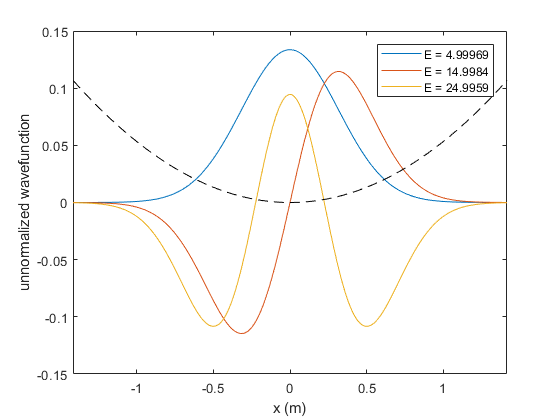

%----------------------------------------------------------------
% Program 4: Find several lowest eigenmodes V(x) and
% eigenenergies E of 1D Schrodinger equation
%     -1/2*hbar^2/m(d2/dx2)V(x) + U(x)V(x) = EV(x)
% for arbitrary potentials U(x).
%----------------------------------------------------------------
% Parameters for solving problem in the interval -L < x < L.
% PARAMETERS: 
L = 5;                   % Interval Length.
N = 1000;                % No of points.
x = linspace(-L, L, N).';% Coordinate vector.
dx = x(2) - x(1);        % Coordinate step.

% POTENTIAL, choose one or make your own.
U = 1/2*100*x.^(2); % quadratic harmonic oscillator potential
%U = 1/2*x.^(4); % quartic potential

% Finite square well of width 2w and depth given.
%w = L/50;
%U = -500*(heaviside(x+w)-heaviside(x-w));

% Two finite square wells of width 2w and distance 2a apart.
%w = L/50;
%a = 3*w;
%U = -200*(heaviside(x+w-a) - heaviside(x-w-a) ... 
% + heaviside(x+w+a) - heaviside(x-w+a));

% Three-point finite-difference representation of Laplacian
% using sparse matrices, where you save memory by only
% storing non-zero matrix elements.
e = ones(N,1);
Lap = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;

% Total Hamiltonian.
hbar = 1;
m = 1;
H = -1/2*(hbar^2/m)*Lap + spdiags(U,0,N,N);

% Find lowest nmodes eigenvectors and eigenvalues of sparse matrix.
nmodes = 3; 
[V,E] = eigs(H,nmodes,'sa');% find eigs.
[E,ind] = sort(diag(E));            % convert E to vector and sort low to high.
V = V(:,ind);                       % rearrange corresponding eigenvectors.

% Generate plot of lowest energy eigenvectors V(x) and U(x).
Usc = 10 * U * max(abs(V(:))) / max(abs(U));% rescale U for plotting.
plot(x,V, x,Usc,'--k');                % plot V(x) and rescaled U(x).
xlabel('x (m)');
ylabel('unnormalized wavefunction');
% Add legend showing Energy of plotted V(x).
legendLabels = [repmat('E = ',nmodes,1), num2str(E)];
legend(legendLabels) % place lengend string on plot.
ax = gca;
ax.XLim = sqrt(2)*[-1 1];

Fig. 1 shows the plot obtained from Program 4 for the potential $U = \frac{1}{2} \cdot 100 \cdot x^2$. Note that the 3 lowest energies displayed in the ﬁgure are just as expected due to the analytic formula


$$(7) \quad E = \hbar \omega \left( n + \frac{1}{2} \right)$$


with $n = \text{integer}$ and $\omega = \sqrt{\frac{k}{m}} = 10\, \text{rad}/\text{s}$.

## 5. A Note on Units in Our Programs

When doing numerical calculations, it is important to minimize the eﬀect of rounding errors by choosing units such that the variables used in the simulation are of the order of unity. In the programs presented here, our focus being undergraduate physics students, we wanted to avoid unnecessarily complicating matters. To make the equations more familiar to the students, we explicitly left constants such as $\hbar$ in the formulas and chose units such that $\hbar = 1$ and $m = 1$. We recognize that others may have other opinions on how to address this issue. An alternative approach used in research is to recast the equations in terms of dimensionless variables, for example by rescaling the energy to make it dimensionless by expressing it in terms of some characteristic energy in the problem. In a more advanced course for graduate students or in a course in numerical methods, such is an approach which would be preferable.

## 6. Time Dependent Phenomena

The separable solutions $|\Psi_E(t)\rangle$ are only a subset of all possible solutions of Eq. (1). Fortunately, they are complete set so that we can construct the general solution *via* the linear superposition


$$(8)\quad |\Psi(t)\rangle = \sum_{E} a_E |\Psi_E(0)\rangle \exp(-i E t / \hbar),$$


where $a_E$ are  constants and the sum is over all possible values of $E$. The important diﬀerence between the separable solutions (5) and the general solution (8) is that the probability densities derived from the general solutions are time-dependent whereas those derived from the separable solutions are not. A very apt demonstration of this is provided in the Program 5 which calculates the time-dependent probability density $\rho(x,t)$ for a particle trapped in a a pair of ﬁnite-square wells whose initial state $|\Psi(0)\rangle$ is set equal to the the equally-weighted superposition


$$(9) \quad |\Psi(0)\rangle = \frac{1}{\sqrt(2)} \left( |\Psi_{e_0}\rangle + |\Psi_{E_1}\rangle\right)$$


of the ground state $|\Psi_{E_0}\rangle$ and the first excited state $|\Psi_{E_1}\rangle$ of the double well system. As snapshots of the program output show in Fig. 2, the particle is initially completely localized in the rightmost well. However, due to $E_0 \neq E_1$, the probability density


$$(10)\quad \rho(x,t) = \frac{1}{2} \left[ |\psi_{E_0}(x)|^2 + |\psi_{E_1}(x)|^2 + 2|\psi_{E_0}(x)||\psi_{E_1}(x)|\cos^2((E_1 - E_0)t/\hbar)\right]$$


is time-dependent, oscillating between the ρ(x) that corresponds to the particle being entirely in the right well


$$(11)\quad \rho(x) = \left| |\psi_{E_0}(x)| + |\psi_{E_1}(x)| \right|^2$$


and $\rho(x)$ for the particle being entirely in the left well


$$(12)\quad \rho(x) = \left| |\psi_{E_0}(x)| - |\psi_{E_1}(x)| \right|^2.$$


By observing the period with which $\rho(x,t)$ oscillates in the simulation output shown in Fig. 2 students can verify that it is the same as the period of oscillation $2\pi\hbar/(E_1 - E_0)$ expected from Eq. (10).

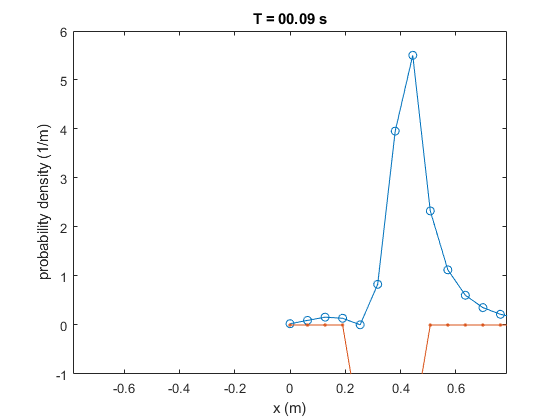

%----------------------------------------------------------------
% Program 5: Calculate Probability Density as a function of time 
% for a particle trapped in a double-well potential.
%----------------------------------------------------------------
% Potential due to two square wells of width 2w 
% and a distance 2a apart.
w = L/50; 
a = 3*w; 
U = -100*( heaviside(x+w-a) - heaviside(x-w-a) ...
         + heaviside(x+w+a) - heaviside(x-w+a));

% Finite-difference representation of Laplacian and Hamiltonian, 
% where hbar = m = 1.
hbar = 1;
e    = ones(N,1);
Lap  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;
H    = -(1/2)*Lap + spdiags(U,0,N,N);

% Find and sort lowest nmodes eigenvectors and eigenvalues of H.
nmodes  = 2; 
[V,E]   = eigs(H,nmodes,'sa'); 
[E,ind] = sort(diag(E)); % Convert E to vector and sort low to high. 
V       = V(:,ind);      % Rearrange coresponding eigenvectors.

% Rescale eigenvectors so that they are always 
% positive at the center of the right well. 
for c = 1:nmodes 
    V(:,c) = V(:,c) / sign(V((3*N/4),c)); 
end

%---------------------------------------------------------------- 
% Compute and display normalized prob. density rho(x,T). 
%---------------------------------------------------------------- 
% Parameters for solving the problem in the interval 0 < T < TF. 
TF = 2*pi*hbar/(E(2)-E(1)); % Length of time interval.
NT = 100;                   % No. of time points.
T  = linspace(0,TF,NT);     % Time vector.

% Compute probability normalization constant (at T=0).
psi_o = 0.5*V(:,1) + 0.5*V(:,2);         % Wavefunction at T=0.
sq_norm = psi_o' * psi_o * dx;          % Square norm = |<ff|ff>|^2.
Usc = 4*U*max(abs(V(:))) / max(abs(U)); % Rescale U for plotting.

% Compute and display rho(x,T) for each time T.
vw = VideoWriter('doubleWell.avi');
open(vw);
for t = 1:NT % time index parameter for stepping through loop.
    % Compute wavefunction psi(x,T) and rho(x,T) at T=T(t).
    psi = 0.5*V(:,1)*exp(-1i*E(1)*T(t)) ...
        + 0.5*V(:,2)*exp(-1i*E(2)*T(t));
    rho = conj(psi) .* psi / sq_norm; % Normalized probability density.
    
    % Plot rho(x,T) and rescaled potential energy Usc.
    plot(x,rho,'o-', x, Usc,'.-');
    axis([-L/8 L/8 -1 6]);
    xlabel('x (m)');
    ylabel('probability density (1/m)');
    title(['T = ' num2str(T(t), '%05.2f') ' s']);
    
    frame = getframe(gcf);
    writeVideo(vw, frame);
end

close(vw);

## 7. Wavepackets and Step Potentials

Wavepackets are another time-dependent phenomenon encountered in undergraduate quantum mechanics for which numerical solution techniques have been typically advocated in the hopes of promoting intuitive acceptance and understanding of approximations necessarily invoked in more formal, analytic treatments. Program 6 calculates and displays the time evolution of a wavepacket for one of two possible potentials, either $U = 0$ or a step potential $U = U_0 \, \Theta(x-L)$. The initial wavepacket is generated as the Fast Fourier Transform of a Gaussian momentum distribution centered on a particular value of the wavevector $k_0$. Because the wavepacket is composed of a distribution of diﬀerent $k\text{s}$, diﬀerent parts of the wavepacket move with diﬀerent speeds, which leads to the wave packet spreading out in space as it moves. 

While there is a distribution of velocities within the wavepacket, two velocities in particular are useful in characterizing it. The phase velocity $v_p = \omega/k = E/p = \hbar k_0 / 2m$ is the velocity of the plane wave component which has wavevector $k_0$. The group velocity $v_g = \hbar k_0 / m$ is the velocity with which the expectation value $\langle x\rangle$ moves and is the same as the classical particle velocity associated with the momentum $p = \hbar k$. Choosing $U = 0$, students can modify this program to plot $\langle x\rangle$ vs $t$. They can extract the group velocity from their numerical simulation and observe that indeed $v_g = 2 v_p$ for a typical wave packet. Students can also observe that, while $v_g$ matches the particle speed from classical mechanics, the wavepacket spreads out as time elapses.

In Program 6, we propagate the wave function forward via the formal solution


$$(13)\quad |\Psi(t)\rangle = \exp(-iHt/\hbar)|\Psi(0)\rangle,$$


where the Hamiltonian matrix $H$ is in the exponential. This solution is equivalent to Eq. (6), as as can be shown by simple substitution. Moreover, MATLAB has no trouble exponentiating the matrix that numerically representing the Hamiltonian operator as long as the matrix is small enough to ﬁt in the available computer memory.

Even more interestingly, students can use this method to investigate scattering of wavepackets from various potentials, including the step potential $U = U_0\,\Theta(x-L/2)$. In Fig. 3, we show the results of what happens as the wavepacket impinges on the potential barrier. The parameters characterizing the initial wavepacket have been deliberately chosen so that the wings do not fall outside the simulation area and initially also do not overlap the barrier on the right. If $\langle E\rangle \ll U_0$, the wavepacket is completely reﬂected from the barrier. If $\langle E\rangle \approx U_0$, a portion of the wave is reﬂected and a portion is transmitted through. If $\langle E\rangle \gg U_0$, almost all of the wave is transmitted.

In Fig. 4 we compare the reﬂection probability $R$ calculated numerically using Program 6 with $R$ calculated by averaging the single-mode[11] expression


$$(14)\quad R(E) = \left| \frac{\sqrt{E} - \sqrt{E-U_0}}{\sqrt{E} + \sqrt{E-U_0}} \right|^2$$


over the distribution of energies in the initial wavepacket. While the numerically and analytically estimated $R$ are found to agree for large and small $\langle E\rangle / U_0$, there is a noticeable discrepancy due to the shortcomings of the numerical simulation for $\langle E\rangle / U_0 \approx 1$. This discrepancy can be reduced signiﬁcantly by increasing the number of points in the simulation to 1600 but only at the cost of signiﬁcantly slowing down the speed of the computation. For our purposes, the importance comparing the analytical and numerical calculations is that it gives students a baseline from which to form an opinion or intuition regarding the accuracy of Eq. (14).

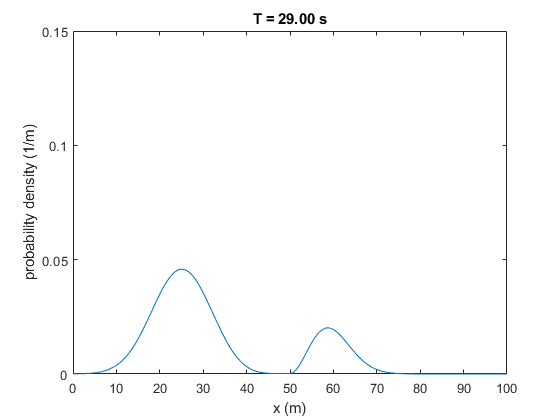

%---------------------------------------------------------------- 
% Program 6: Wavepacket propagation using exponential of H.
%---------------------------------------------------------------- 
% Parameters for solving the problem in the interval 0 < x < L.
L = 100;               % Interval Length.
N = 400;               % No of points.
x = linspace(0,L,N).'; % Coordinate vector.
dx = x(2) - x(1);      % Coordinate step.

% Parameters for making intial momentum space wavefunction phi(k).
ko = 2;                   % Peak momentum.
a  = 20;                  % Momentum width parameter.
dk = 2*pi/L;              % Momentum step.
km = N*dk;                % Momentum limit.
k  = linspace(0,+km,N).'; % Momentum vector.

% Make psi(x,0) from Gaussian kspace wavefunction phi(k) using
% fast fourier transform.
phi = exp(-a*(k-ko).^2) .* exp(-1i*6*k.^2); % Unnormalized phi(k).
psi = ifft(phi);                   % Multiplies phi by expikx and integrates vs x.
psi = psi / sqrt(psi' * psi * dx); % Normalize psi(x,0).

% Expectation value of energy; e.g. for the parameters
% chosen above <E> = 2.062.
avgE = phi' * 0.5*diag(k.^2,0) * phi * dk / (phi' * phi * dk);

% CHOOSE POTENTIAL U(X): Either U = 0 OR
% U = step potential of height avgE that is located at x = L/2.
%U = 0*heaviside(x-(L/2));    % Free particle wave packet evolution.
U = avgE*heaviside(x-(L/2)); % Scattering off step potential.

% Finite-difference representation of Laplacian and Hamiltonian.
e   = ones(N,1);
Lap = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;
H   = -(1/2)*Lap + spdiags(U,0,N,N);

% Parameters for computing psi(x,T) at different times 0 < T < TF.
NT = 200;               % No. of time steps.
TF = 29;
T  = linspace(0,TF,NT); % Time vector.
dT = T(2) - T(1);       % Time step
hbar = 1;

% Time displacement operator.
E = expm(-1i * full(H) * dT / hbar);

%----------------------------------------------------------------
% Simulate rho(x,T) and plot for each T
%----------------------------------------------------------------
vw = VideoWriter('propagation.avi');
open(vw);
for t = 1:NT % Time index for loop.
    % Calculate probability density rho(x,T).
    psi = E * psi;          % Calculate new psi from old psi.
    rho = conj(psi) .* psi; % rho(x,T).
    
    plot(x,rho);
    axis([0 L 0 0.15]);
    xlabel('x (m)');
    ylabel('probability density (1/m)');
    title(['T = ' num2str(T(t), '%05.2f') ' s']);
    
    frame = getframe(gcf);
    writeVideo(vw, frame);
end

close(vw);

% Calculate Reflection probability
R = 0;
for a = 1:floor(N/2)
    R = R + rho(a);
end
R = R * dx;
disp(R);

    0.7765



## 8. Conclusions

One beneﬁt of incorporating numerical simulation into the teaching of quantum mechanics, as we have mentioned, is the development of student intuition. Another is showing students that non-ideal, real-world problems can be solved using the concepts they learn in the classroom. However, our experimentation incorporating these simulations in quantum physics at WPI during the past year has shown us that the most important beneﬁt is a type of side-eﬀect to doing numerical simulation: the acceptance on an intuitive level by the student that functions are like vectors and diﬀerential operators are like matrices. While in the present paper, we have only had suﬃcient space to present the most illustrative MATLAB codes, our goal is to eventualy make available a more complete set of polished codes available for downloading either from the authors or directly from the ﬁle exchange at MATLAB Central.[14]

## References

- P. A. M. Dirac, [The Principles of Quantum Mechanics](https://global.oup.com/academic/product/the-principles-of-quantum-mechanics-9780198520115?q=dirac&lang=en&cc=us), 1st ed., (Oxford University Press, 1930).

- Born’s law is stated as a proportionality because an additional factor is necessary depending on the units of $|\Psi\rangle$.

- C. C. Silva and R. de Andrade Martins, “Polar and axial vectors versus quaternions,” Am. J. Phys. 70, 958-963 (2002).

- R. W. Robinett, Quantum Mechanics: Classical Results, Modern Systems, and Visualized Examples, (Oxford University Press, 1997).

- H. Gould, “Computational physics and the undergraduate curriculum,” Comput. Phys. Commun. 127, 610 (2000); J. Tobochnik and H. Gould, “Teaching computational physics to undergraduates,” in Ann. Rev. Compu. Phys. IX, edited by D. Stauﬀer (World Scientiﬁc, Singapore, 2001), p. 275; H. Gould, J. Tobochnik, W. Christian, An Introduction to Computer Simulation Methods: Applications to Physical Systems, (Benjamin Cummings, Upper Saddle River, NJ, 2006) 3rd ed..

- R. Spenser, “Teaching computational physics as a laboratory sequence,” Am. J. Phys. 73, 151-153 (2005). 

- D. Styer, “Common misconceptions regarding quantum mechanics," Am. J. Phys. 64, 31-34 (1996).

- A. Goldberg, H. M. Schey, J. L. Schwartz, “ComputerGenerated Motion Pictures of One-Dimensional QuantumMechanical Transmission and Reﬂection Phenomena,” Am. J. Phys. 35, 177-186 (1967). 

- C. Singh, M. Belloni, and W. Christian, “Improving students’ understanding of quantum mechanics,” Physics Today, August 2006, p. 43.

- These MATLAB commands are explained in an extensive on-line, tutorial within MATLAB and which is also independently available on the MathWorks website, [http://www.mathworks.com/](http://www.mathworks.com/). 

- D. J. Griﬃths, Introduction to Quantum Mechanics, 2nd Ed., Prentice Hall 2003.

- A. Garcia, Numerical Methods for Physics, 2nd Ed., (Prentice Hall, 1994). 

- G. Lindblad, “Quantum Mechanics with MATLAB,” available on internet, [http://mathphys.physics.kth.se/schrodinger.html](http://mathphys.physics.kth.se/schrodinger.html). 

- See the File Exchange at [http://www.mathworks.com/matlabcentral/](http://www.mathworks.com/matlabcentral/).